# ECE 1395 Project:

## Chess Evaluator

**Names:** Benjamin Bryla, Gabriel Yeniceri

clear; clc

## Thresholds

IsEqual=75; %Position is equal if equal to or inbetween +# and -#

%If checkmate exists, force evaluation to be
CheckmateThreshold=1000; %Setting evaluation to 2000 if a side has mate threat

# Data Preprocessing:

#### Loading Data:

%Read filename and input into array
filename = "input\dataset_eval.csv";

%Options for getting CSV file read correct
options=detectImportOptions(filename);
options=setvartype(options,["Var2","Var4"],"string");
options.Delimiter = ',';
options.VariableNamingRule = 'preserve';

Data = readtable(filename, options);

Cleanup

clearvars options filename

#### Split data into Position and Evaluation

FEN = Data{:,2};
Eval = Data{:,4};

## Evaluation Pre-Process:

%Modify mate on boards
is_M = contains(Eval(:),'M'); %If Mate is on Board
is_EvalMinus = ~contains(Eval(:),'-'); %If evaluation contains a - 

IsMate=((is_EvalMinus-0.5)*2).*is_M*CheckmateThreshold; %Mating Threat new evals
IsMateShort=IsMate(IsMate~=0);

%Change eval from Relative based on turn, to Absolute based on White
is_WhiteTurn = contains(FEN(:),'w'); %If is White's Turn

EvalAbsolute=(is_WhiteTurn-0.5)*2;

%Update Mate on Board
Eval(is_M)=IsMateShort; 
%Update Relative eval to Absolute Eval
Eval=str2double(Eval);
Eval=Eval.*EvalAbsolute;

Cleanup

clearvars is_M is_M is_EvalMinus IsMate IsMateShort EvalAbsolute Data

## Bitboard Pre-Process:

Converts FEN notation to Bitboard Representation

%Splits bitboard into Board, and Extras
SplitFEN=split(FEN); %Index 1 is Board, Index 2-6 is extra information
%Board Split
Board=split(SplitFEN(:,1),'/');

BoardExtra=SplitFEN(:,2:end);

#### Written:

At this point we have the board, m x 8 string, each column represents a chess board column. BoardExtra is split up into 5 columns, turn, Castling rights, Enpassant rights, half move clock, full move number. 

cleanup

clearvars SplitFEN

## Bitboard Creation

FEN to Piece Board function. Takes in the board split from above

%Create a Piece Board
function PieceBoard=FEN2Piece(Board)
    PieceBoard=zeros(1,8*8);
    L=strlength(Board);
    for dataNum=1:height(Board) %For every data set
        CurrBoard = Board(dataNum,:);
        rowIndex=1;
        for column=1:8 %For every column of chess board
            CurrRow = CurrBoard(column);
            for row=1:L(dataNum,column) %For the rows of the chess board
                charRow=CurrRow{1}(row);
                if isstrprop(charRow, 'digit') %If number is found add it's value to index
                    rowIndex = rowIndex + str2double(charRow);
                else %If character is found
                    PieceBoard(dataNum,rowIndex)=charRow; %If char is found, set char
                    rowIndex=rowIndex+1;
                end
            end
        end
    end
end

Piece to Bit Board function

function BitBoard=Piece2Bit(Piece)
%List of pieces
pieceList='pbnrqkPBNRQK';
BitBoard=false(1,8*8*12);
    for squareIndex=1:64 %Check every square for if it contains a piece
        for pieceIndex=1:12
            if pieceList(pieceIndex)==Piece(squareIndex)
                BitIndex=squareIndex+64*pieceIndex-64; %Calculate index of the bitboard square
                BitBoard(BitIndex)=1; %And set to true
            end
        end
    end
end

Converts the Board representation into Bitboards

%Number of data points to use
m=height(Board);

m = 341019

m=1000;

%Setup Empty Arrays
Data=Board(1:m,:);
PieceBoard=zeros(height(Data),8*8);
BitBoard=false(height(Data),8*8*12);

%Convert to piece board
tic
for i=1:m
    PieceBoard(i,:)=FEN2Piece(Board(i,:));
    BitBoard(i,:)=Piece2Bit(PieceBoard(i,:));
end
timeElapsed=toc

timeElapsed = 25.7747

fprintf("Time to convert %d FEN to bitboard: %0.5f\n",m,timeElapsed)

Time to convert 341019 FEN to bitboard: 25.77470



%Convert to Char
PieceBoard=char(PieceBoard);
%Fill in Empty
PieceBoard(PieceBoard==0)='~';

## FEN Conversion Verification

Testing: Check current board state based on index

index=285;

index = 285

ShowBoard=reshape(PieceBoard(index,:),8,8)';
disp("Show the current board state")

Show the current board state


disp(ShowBoard)

~~~~~rk~
~b~~r~p~
pp~b~~~p
~~~pqp~~
~~~N~~~~
~~~~PB~P
PP~~~PP~
R~~QR~K~



pieceList='pbnrqkPBNRQK';
for i=0:11
    disp(pieceList(i+1))
    disp(reshape(BitBoard(index,64*i+1:64*i+64),8,8)')
end

p


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   1   0
   1   1   0   0   0   0   0   1
   0   0   0   1   0   1   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



b


   0   0   0   0   0   0   0   0
   0   1   0   0   0   0   0   0
   0   0   0   1   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



n


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



r


   0   0   0   0   0   1   0   0
   0   0   0   0   1   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



q


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



k


   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



P


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   1
   1   1   0   0   0   1   1   0
   0   0   0   0   0   0   0   0



B


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   1   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



N


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



R


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   1   0   0   0   1   0   0   0



Q


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   0



K


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   1   0



The current board state in an array is the same that chess.com gives. 

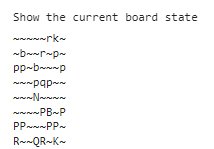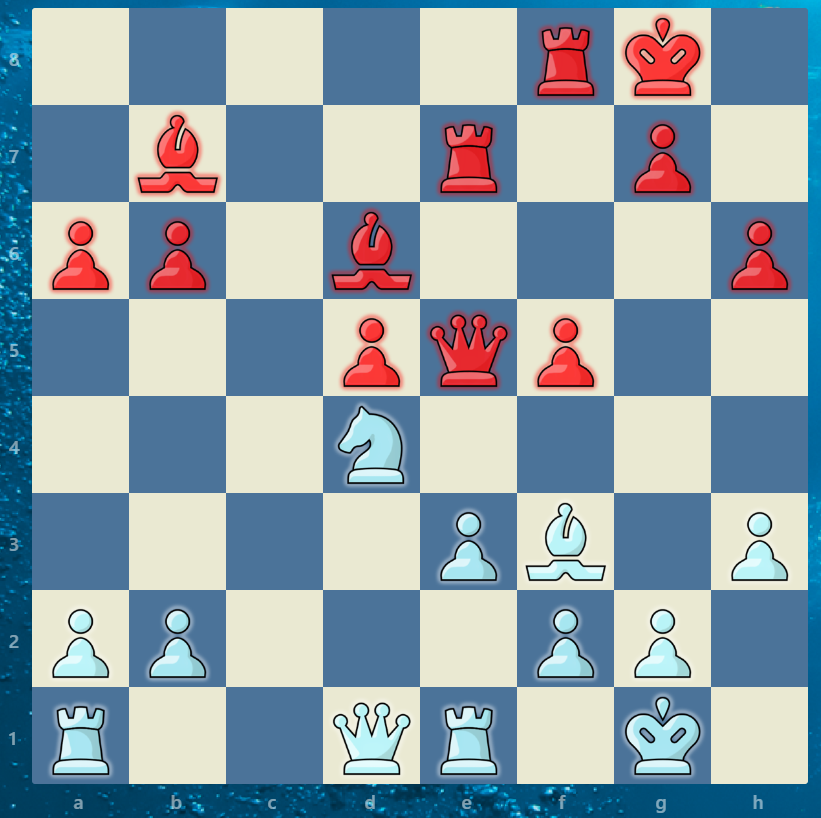

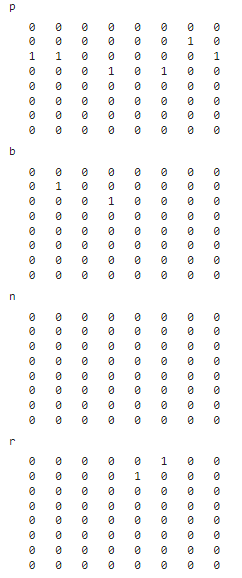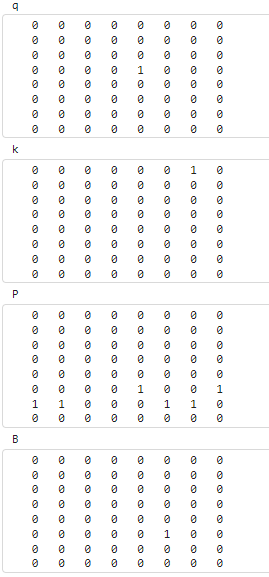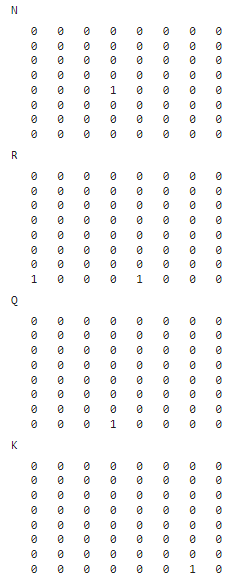

When looking at the bit board, it aligns with the location of pieces for FEN notation. Lowercase = Black pieces. Uppercase = White Pieces. The position is aligned with the standard chess board position. 